# MIE301 Lab 4

## Starter Code - Calculate mechanism motion and plot it

close all; % closes all figures
clear all; % clears all variables from memory
clc;       % clears all calculations from the Matlab workspace

% Plot Parameters: these will be used to set the axis limits on the figure
% (units: 'm')
xmin= -0.4; % leftmost window edge
xmax= 0.3;  % rightmost window edge
ymin= -0.2; % bottom window edge
ymax= 0.6;  % top window edge

% Crank rotation angles (theta2)

theta2_deg=(0:4:360);     %forming the theta2 vector in degrees
theta2=pi/180*theta2_deg; %converting the degrees to radians
steps=length(theta2);     %calculating the length of the theta2 vector

% Dimensions of links and offset 
r2= 15/100;           % link #2 length r2, m
r3= 45/100;           % link #3 length r3, m
b = 20/100;           % offset, m
m = 0.8;              % mass of slider (kg)
g = 9.81;             % gravity in m/s^2
% set up figure
figure;                       %create new figure
%set(1,'WindowStyle','Docked')    %dock the figure

## calculate mechanism motion and plot it

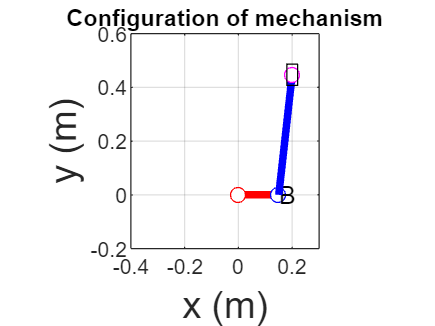

for i=1:steps                             % step through motion of the mechanism
    hold off;    
    
    % Draw Link 2:
    Ax(i) = 0;                            % pivot point of link 2 position
    Ay(i) = 0;                            % pivot point of link 2 position
    Bx(i) = r2*cos( theta2(i) );          % x-position of point B
    By(i) = r2*sin( theta2(i) );          % y-position of point B
    plot( [Ax(i) Bx(i)], [Ay(i), By(i)],'Color','r','LineWidth',3 ); % draw the link from A to B for the current configuration
    hold on;
    grid on;    
    
    % Draw Base Pivot:
    recsz = 0.02;                                   % size of drawn base pivot
    plot([0,recsz],[0,-recsz],'r');                 % draw base pivot
    plot([0,-recsz],[0,-recsz],'r');                % draw base pivot
    plot(0,0,'ro','MarkerFaceColor','w');           % draw a small circle at the base pivot point
    plot(Bx(i), By(i), 'bo','MarkerFaceColor','w'); % draw a small circle at B
    text(Bx(i)+.002, By(i), 'B','color','k');       % label point B    
    
    % Calculate D here:
    theta3(i) = acos((b-Bx(i))/r3);                 % angle theta_3
    Cx(i) = b;                                      % x-position of point C
    Cy(i) = r2*sin(theta2(i))+ r3*sin(theta3(i));   % y-position of point C
    
    % Draw Link 3:
    plot( [Bx(i), Cx(i)], [ By(i), Cy(i)],'Color','b','LineWidth',3 ); % draw the link from B to C for the current configuration
    plot(Cx(i),Cy(i),'mo','MarkerFaceColor','w');           % draw a small circle at the piston pivot point C
    
    % Draw piston:
    rectangle('position',[ Cx(i)-.02, Cy(i)-.04, 0.04, .08 ] ); % draw the piston itself [x y w h]
    
    % Figure properties 
    hold on;                           % draw on top of the current figure
    xlabel('x (m)', 'fontsize', 15);   % axis label
    ylabel('y (m)', 'fontsize', 15);   % axil label 
    axis equal;                        % make sure the figure is not stretched
    title('Configuration of mechanism');  % add a title to the figure
    axis( [xmin xmax ymin ymax] );        % figure axis limits 
    %pause(0.05);                          % wait to proceed to next configuration, seconds
end

## Part I - Quasi-Static Force Analysis

## b): Plot torque for cases with finite and negligible mass of slider

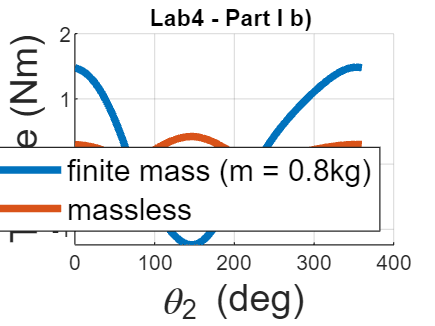

% find the theta2 at max and min position in order to find the direction of
% friction force during rotation

for i=1:steps                        % step through motion of the mechanism
    Bx(i) = r2*cos(theta2(i));     
    theta3(i) = acos((b-Bx(i))/r3);
    D(i) = r2*sin(theta2(i))+ r3*sin(theta3(i));
end
    [maxD, IndDmax] = max(D);    % max position of slider
    [minD, IndDmin] = min(D);    % min position of slider
    theta2_max=theta2(IndDmax);  % theta2 at maximum D
    theta2_min=theta2(IndDmin);  % theta2 at minimum D

% find torque;-
%Step1: write the condition to define the direction of friction force
%Step2: compute torque

m_vec = [m 0];  % creating a vector masses; 1st value is 0.8 second is 0 (mass and massless case)
for j=1:length(m_vec)  %step through different mass
    for i=1:steps

        % write nested condition do define the direction of friction force
         if  theta2(i) == theta2_min || theta2(i) == theta2_max
             F=0;
         elseif theta2(i) < theta2_max || theta2(i) > theta2_min
             F=2;
         else
             F=-2;
         end
        
        % compute torque 
        F34 = (m_vec(j)*g + F)/(sin(theta3(i)));
        F32 = -F34;
        M2(i,j) = -r2*F32*sin(theta3(i)-theta2(i)); % torque to be applied by motor, CCW+

    end
end

figure;  % setup figure
%set(2,'WindowStyle','Docked')    %dock the figure
hold on;
plot(theta2*180/pi, M2,'LineWidth',3); % plot M2 array
hold off
grid on  
legend('finite mass (m = 0.8kg)','massless','Location', 'southeast',fontsize=12)
xlabel('\theta_2 (deg)', 'fontsize', 15); 
ylabel('Torque (Nm)', 'fontsize', 15);   
title('Lab4 - Part I b) ');


% Written ans:
% Mass case: initially, M2 (CCW) is positive as you need to lift the slider. When
% the slider comes down, a negative (CW) Moment is needed toallow for
% equillibrium. 
% Massless case: M2 is always positive, as the slider must be 'dragged'
% against friction in both up and down directions

## Part I, c): Find the angle at which motor experiences absolute peak torque in both cases

for j = 1:length(m_vec)

    % max absolute torque and the index at which it occurs

    if j == 1
        [M_max_case_1, M_max_case_1_ind] = max(abs(M2(:,j))); % Get case 1 index
        case_1_max_angle = theta2(M_max_case_1_ind);
    elseif j == 2
        [M_max_case_2, M_max_case_2_ind] = max(abs(M2(:,j))); % Get case 2 index
        case_2_max_angle = theta2(M_max_case_2_ind);
    end
    % angle at which maxmimum torque occurs in degree
end
case_1_max_angle_deg = case_1_max_angle *180/pi

case_1_max_angle_deg = 352.0000

case_2_max_angle_deg = case_2_max_angle *180/pi

case_2_max_angle_deg = 148

## Part I, d): Work Calculations for both cases

stroke = maxD - minD;
frictional_work_with_mass = (- m*g*stroke + m*g*stroke + 2*F*stroke)

frictional_work_with_mass = 1.3680

frictional_work_massless = 2*F*stroke  % Friction acts while going up and down

frictional_work_massless = 1.3680


for j=1:length(m_vec)
    work = 0;
    for i = 1:steps-1
        MW_partial = M2(i,j)*(theta2(i+1)-theta2(i)); % calulate the partial work
        work = work + MW_partial;        % sum partial works
    end
    motor_work(j) = work;  %storing the value of motor work for jth mass
end

disp(motor_work)   %displaying the work of motor for both cases

    1.3675    1.3675



% The Work in both cases are the same because work due to gravity in case one cancels out
% Total gravity work = m*g*d*cos(180*) - m*g*d*cos(0*) = -m*g*d + m*g*d = 0

% save the value of M2 vector for a=2cm as it is needed in the Part II f.)
M2_static=M2(:,1);

## Part II, Dynamic Force Analysis

clearvars -except M2_static   % clear all variables except variable on line 140

% Crank rotation angles (theta2)
theta2_deg=(0:4:360);
theta2=pi/180*theta2_deg;
steps=length(theta2);

% Mechanism parameters
r2= 15/100;           % link #2 length r2, m
r3= 45/100;           % link #3 length r3, m
b = 20/100;           % offset, m
m = 0.8;              % mass of slider (kgs)
g = 9.81;             % gravity in m/s^2

## f): Compute the torque at various speeds for m = 0.8 kg

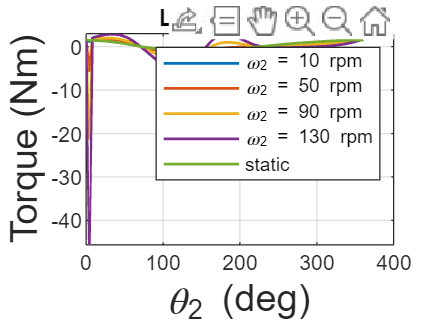

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Numerical approach

%calculate theta3
theta3 = acos((b - r2*cos(theta2))/r3);

%calculate D
D = r2*sin(theta2) + r3*sin(theta3); 

%initialize rotation rate vector 
theta2_dot = 10:40:130; % rpm
rpm_steps = length(theta2_dot); %number of speeds for which analysis is performed

for j=1:rpm_steps
    
    %forming the time vector 
    t_rev=60/theta2_dot(j);  % finding time per revolution in seconds
    time=linspace(0,t_rev,steps);  %time vector

    %form velocity vector, prepend 0 and store it for jth motor spped
    D_dot = diff(D)./diff(time);                   % velocities for a given speed
    D_dot = [0, D_dot];                            % prepend zero to keep the length of the vector same as time vector
    velocity(:,j) = D_dot;                         % calculated velocity stored for a given motor speed
    
    %form acceleration vector, prepend 0 and store it for jth motor spped
    D_double_dot = diff(D_dot)./diff(time);        % acceleration for a given speed
    D_double_dot = [0, D_double_dot];               % prepend zero to keep the length of the vector same as time vector
    acceleration(:,j) = D_double_dot;      % calculated acceleration stored for a given motor speed
    
    for i=1:steps
        
        %write the if-else condition which determines the direction of
        %friction force using velocity this time 

        if  velocity(i,j) > 0
            F = 2;
        elseif velocity(i, j) == 0
            F = 0;
        else
            F = -2;
        end

        % compute torque (maths explained in the lab)
        F34 = (m*g + F - m*acceleration(i,j))/(sin(theta3(i)));
        F32 = -F34;
        M2(i,j) = -r2*F32*sin(theta3(i)-theta2(i)); % torque to be applied by motor, CCW+, so the negative accounts for that
    end
end

% setup figure 3
figure; 
%set(3,'WindowStyle','Docked')

% plot the M2 vector for all the rotation speeds and M2 vector for static case
plot(theta2*180/pi, M2,theta2*180/pi,M2_static,'LineWidth',1.1);

% plotting details
grid on
legend('\omega_2 = 10 rpm','\omega_2 = 50 rpm','\omega_2 = 90 rpm','\omega_2 = 130 rpm','static')
xlabel('\theta_2 (deg)', 'fontsize', 15); 
ylabel('Torque (Nm)', 'fontsize', 15);   
title('Lab4 - Part II f)');